# SPECTER 1-DOF Vertical Flight Dynamics Model 

clear
clc
close all

## Initial Conditions

h0 = 0;
v0 = 0;
x0 = [h0; v0];

## Parameters

p.mWet = 10;     % kg
p.mDry = 9;      % kg


p.thrustTime = [0 0.1 0.3 1.0 1.8 2.0];
p.thrustData = [0 150 220 210 180 0];

p.tb = p.thrustTime(end);

p.Cd = 0.5;
p.A = 0.01;   % m^2

## Environment

p.g = 9.80665;

p.T0_atm = 288.15;  % K
p.P0 = 101325;      % Pa
p.L = 0.0065;       % K/m
p.R = 287.05;       % J/(kg*K)
p.gamma = 1.4;

## Simulation

tfinal = 20;

dynamics = @(t,x) SpecterDynamics(t,x,p);

solverOptions = odeset('RelTol',1e-9,'AbsTol',1e-11);

[t1,x1] = ode45(dynamics,[0,p.tb],x0,solverOptions);

x_burnout = x1(end,:).';

options = odeset('Events', @ApogeeEvent);

[t2,x2,te,xe,ie] = ode45(dynamics,[p.tb tfinal],x_burnout,options);

t = [t1;t2(2:end)];
x = [x1;x2(2:end,:)];

h = x(:,1);
v = x(:,2);

## Post-Processing

hb_sim = x1(end,1);
vb_sim = x1(end,2);

h_apogee = xe(1);
t_apogee = te;

% Atmospheric flight conditions
Mach = zeros(size(t));
rho_history = zeros(size(t));

for k = 1:length(t)

    [~,~,rho,a] = AtmosphereModel(h(k),p);

    rho_history(k) = rho;
    Mach(k) = abs(v(k))/a;

end

% Maximum Mach
[maxMach,iMach] = max(Mach);

t_maxMach = t(iMach);
h_maxMach = h(iMach);

% Dynamic pressure
q = 0.5*rho_history.*v.^2;

[maxQ,iQ] = max(q);

t_maxQ = t(iQ);
h_maxQ = h(iQ);
v_maxQ = v(iQ);

% Acceleration
acceleration = zeros(size(t));

for k = 1:length(t)

    dx = SpecterDynamics(t(k),x(k,:).',p);
    acceleration(k) = dx(2);

end

[maxAcceleration,iAccel] = max(acceleration);

t_maxAccel = t(iAccel);
h_maxAccel = h(iAccel);

% Mass history

mass = zeros(size(t));

for k = 1:length(t)
    mass(k) = MassModel(t(k),p);
end

% Total impulse
totalImpulse = trapz(p.thrustTime,p.thrustData);

## Results

fprintf('\n--- SPECTER 1-DOF RESULTS ---\n\n');


--- SPECTER 1-DOF RESULTS ---




fprintf('BURNOUT\n');

BURNOUT


fprintf('Altitude: %.3f m\n', hb_sim);

Altitude: 19.960 m


fprintf('Velocity: %.3f m/s\n\n', vb_sim);

Velocity: 19.091 m/s




fprintf('APOGEE\n');

APOGEE


fprintf('Altitude: %.3f m\n', h_apogee);

Altitude: 38.427 m


fprintf('Time: %.3f s\n\n', t_apogee);

Time: 3.939 s




fprintf('PROPULSION\n');

PROPULSION


fprintf('Total impulse: %.3f N*s\n\n', totalImpulse);

Total impulse: 369.000 N*s




fprintf('MAXIMUM MACH\n');

MAXIMUM MACH


fprintf('Mach: %.4f\n', maxMach);

Mach: 0.0576


fprintf('Time: %.3f s\n', t_maxMach);

Time: 1.891 s


fprintf('Altitude: %.3f m\n\n', h_maxMach);

Altitude: 17.840 m




fprintf('MAX-Q\n');

MAX-Q


fprintf('Dynamic pressure: %.3f Pa\n', maxQ);

Dynamic pressure: 234.475 Pa


fprintf('Time: %.3f s\n', t_maxQ);

Time: 1.891 s


fprintf('Altitude: %.3f m\n', h_maxQ);

Altitude: 17.840 m


fprintf('Velocity: %.3f m/s\n\n', v_maxQ);

Velocity: 19.582 m/s




fprintf('MAXIMUM ACCELERATION\n');

MAXIMUM ACCELERATION


fprintf('Acceleration: %.3f m/s^2\n', maxAcceleration);

Acceleration: 12.528 m/s^2


fprintf('Acceleration: %.3f g\n', maxAcceleration/p.g);

Acceleration: 1.277 g


fprintf('Time: %.3f s\n', t_maxAccel);

Time: 0.300 s


fprintf('Altitude: %.3f m\n', h_maxAccel);

Altitude: 0.084 m


## Verification

%% Verification

p_verify = p;
p_verify.Cd = 0;

dynamics_verify = @(t,x) SpecterDynamics(t,x,p_verify);

[t_verify_ode,x_verify] = ode45( ...
    dynamics_verify,[0 p_verify.tb],x0,solverOptions);

vb_verify = x_verify(end,2);

t_verify = linspace(0,p_verify.tb,10000);

T_verify = zeros(size(t_verify));
m_verify = zeros(size(t_verify));

for k = 1:length(t_verify)

    T_verify(k) = ThrustModel(t_verify(k),p_verify);
    m_verify(k) = MassModel(t_verify(k),p_verify);

end

vb_reference = trapz(t_verify,T_verify./m_verify) ...
    - p_verify.g*p_verify.tb;

verification_error = abs(vb_verify-vb_reference);

fprintf('\n--- VERIFICATION ---\n');


--- VERIFICATION ---


fprintf('ODE45 burnout velocity: %.9f m/s\n',vb_verify);

ODE45 burnout velocity: 19.185711334 m/s


fprintf('Independent reference: %.9f m/s\n',vb_reference);

Independent reference: 19.185711222 m/s


fprintf('Velocity difference: %.12f m/s\n',verification_error);

Velocity difference: 0.000000112573 m/s


## Plots

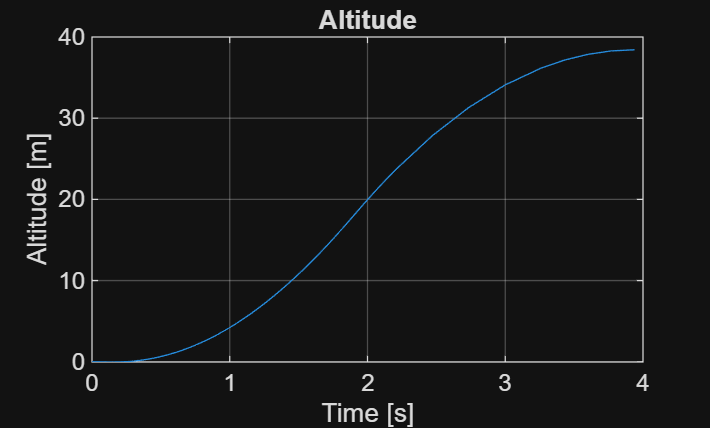

figure
plot(t,h)
xlabel('Time [s]')
ylabel('Altitude [m]')
title('Altitude')
grid on

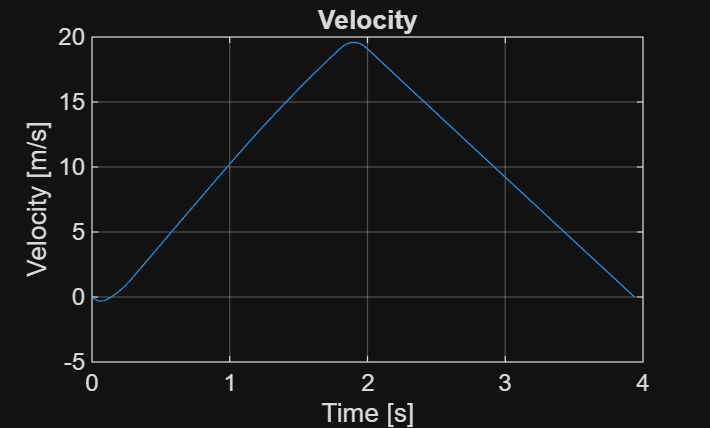


figure
plot(t,v)
xlabel('Time [s]')
ylabel('Velocity [m/s]')
title('Velocity')
grid on

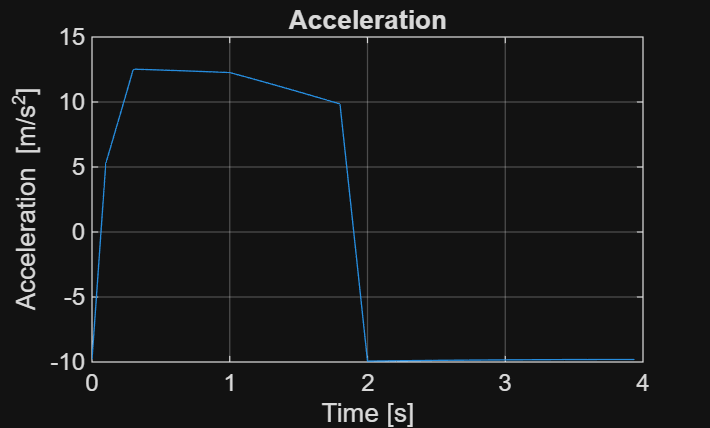


figure
plot(t,acceleration)
xlabel('Time [s]')
ylabel('Acceleration [m/s^2]')
title('Acceleration')
grid on

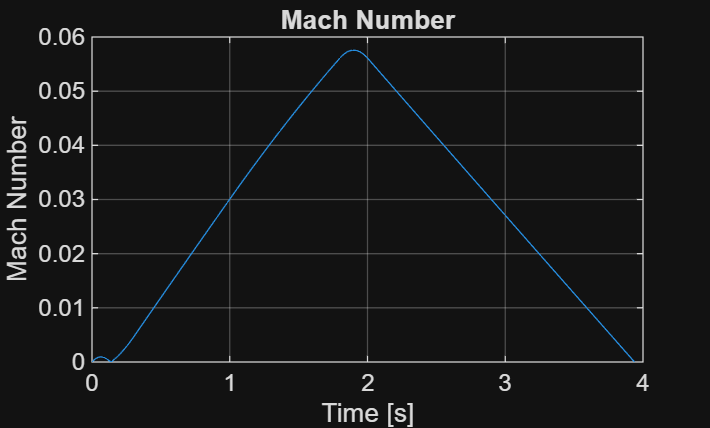


figure
plot(t,Mach)
xlabel('Time [s]')
ylabel('Mach Number')
title('Mach Number')
grid on

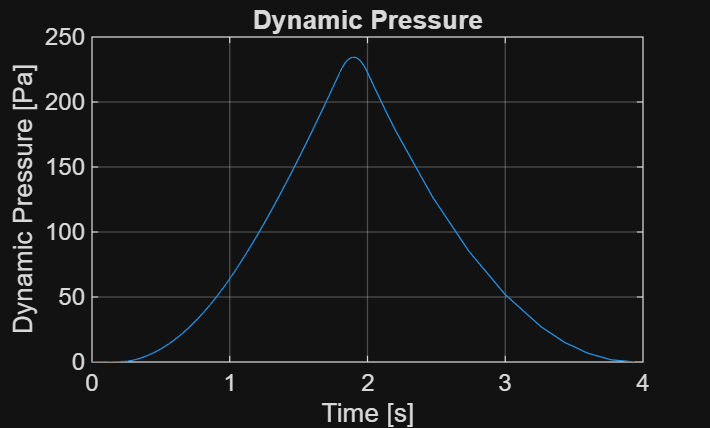


figure
plot(t,q)
xlabel('Time [s]')
ylabel('Dynamic Pressure [Pa]')
title('Dynamic Pressure')
grid on

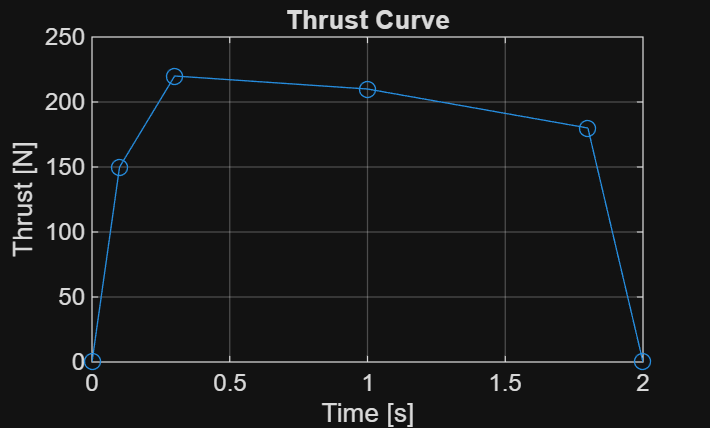


figure
plot(p.thrustTime,p.thrustData,'o-')
xlabel('Time [s]')
ylabel('Thrust [N]')
title('Thrust Curve')
grid on

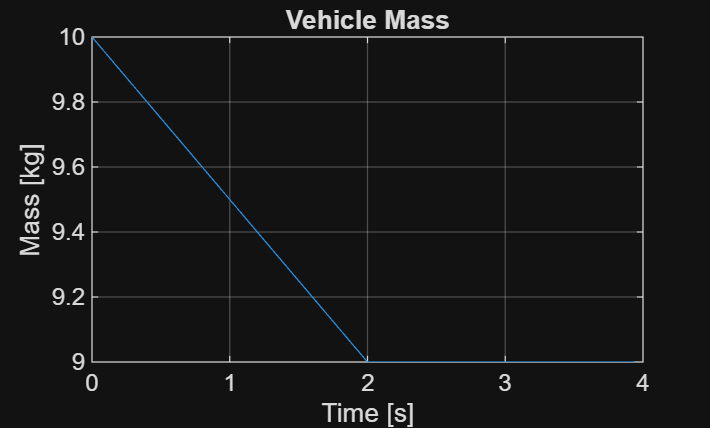


figure
plot(t,mass)
xlabel('Time [s]')
ylabel('Mass [kg]')
title('Vehicle Mass')
grid on